clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["Sample1", "Sample2", "Sample3", "SampleA", "SampleB", "SampleC"];
categories = ["1", "2", "3", "A", "B", "C"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    matFiles = dir(fullfile(folderPath, "*.mat"));

    for j = 1:length(matFiles)
        matFilePath = fullfile(folderPath, matFiles(j).name);
        image = load(matFilePath).imageArray;
        
        allData = [allData; {image, categories(i)}];
    end
end

% define images & labels
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
images = zeros(imageSize(1), imageSize(2), 1, numImages);

for i = 1:numImages
    images(:, :, 1, i) = allData.Image{i};
end

labels = categorical(allData.Label);

% split data into train and test set
cv = cvpartition(labels, 'HoldOut', 0.2);
trainIdx = training(cv);
testIdx = test(cv);
trainImages = images(:, :, :, trainIdx);
trainLabels = labels(trainIdx);
testImages = images(:, :, :, testIdx);
testLabels = labels(testIdx);

% Define the layers of the CNN
layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(numel(categories))
    softmaxLayer
    classificationLayer
    ];

% Training options
options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       16.41% |       26.66% |       2.2535 |       2.0679 |          0.0100 |
|       1 |          30 |       00:00:06 |       92.97% |       92.95% |       0.2532 |       0.2397 |          0.0100 |
|       2 |          50 |       00:00:07 |       92.97% |              |       0.1932 |              |          0.0100 |
|       2 |          60 |       00:00:07 |       96.88% |       95.49% |       0.0968 |   

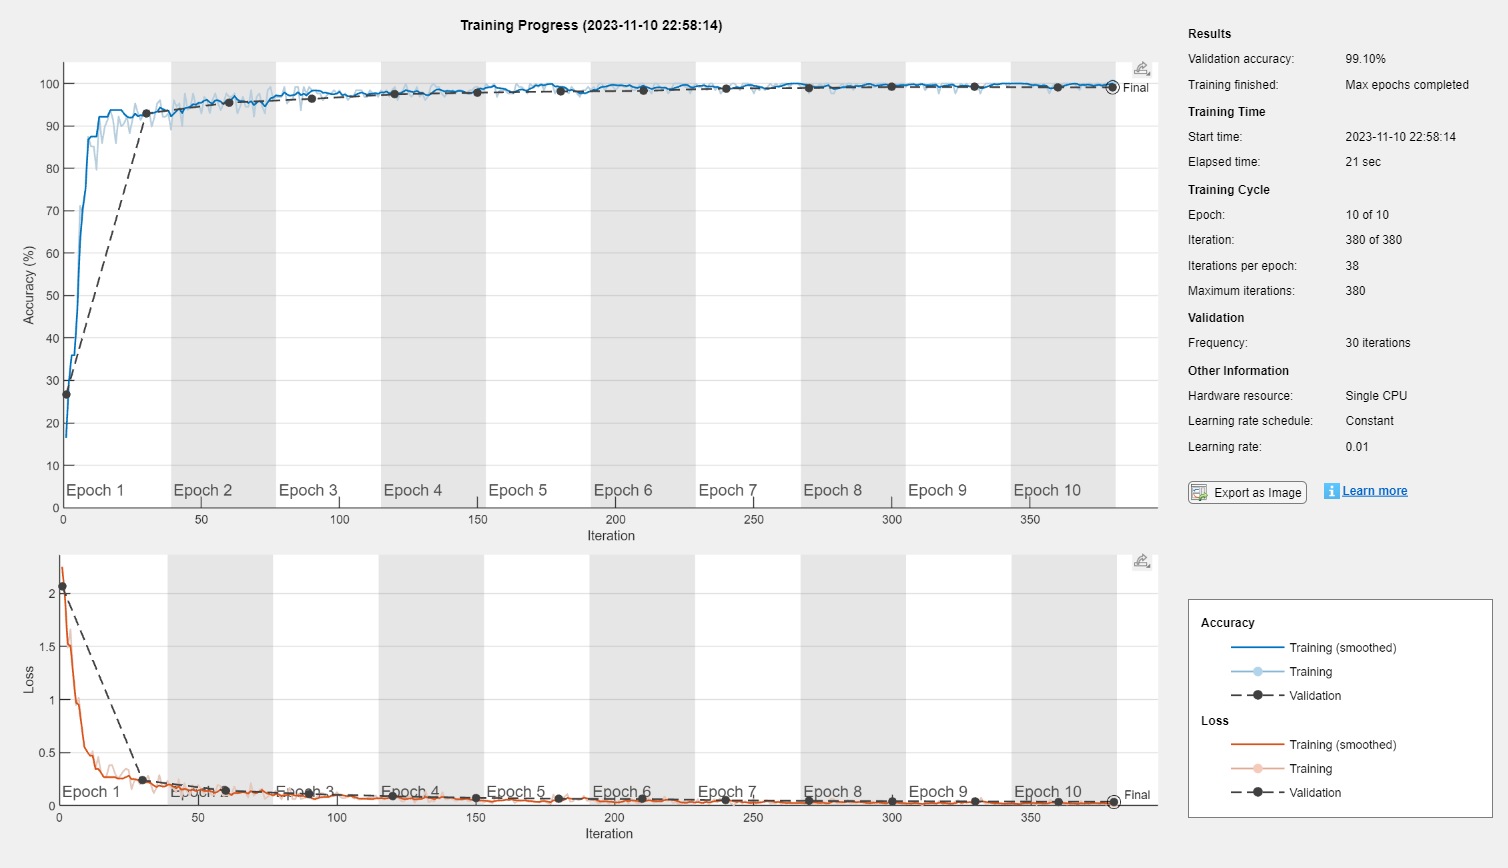

% Train the CNN
net = trainNetwork(trainImages, trainLabels, layers, options);

% Classify Test Images
predictedLabels = classify(net, testImages);

% Calculate the Accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 99.10%
